clc, clear all

xs= 300;
zs= 500;

xr= 1300;
zr= 100;

seconds = 1;
bandwidth =  500;
deep = 3000;
h = deep;
j = 4;
c = 1450;

[s,s_t,g,t] = greens(seconds,bandwidth, xs, zs, xr,zr, j, h, c);

g = -1.4877e-09

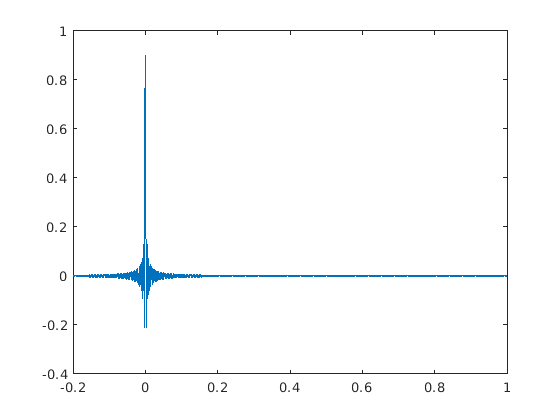

plot(t,s)

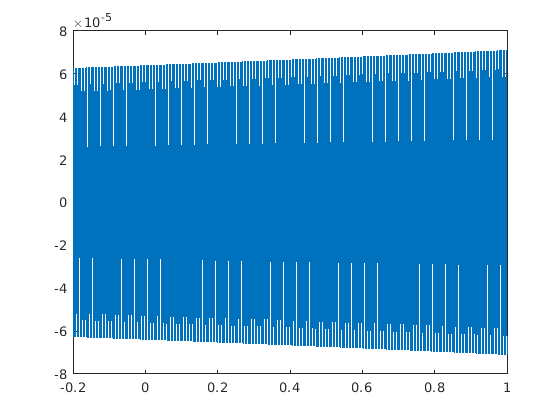

plot(t,s_t)

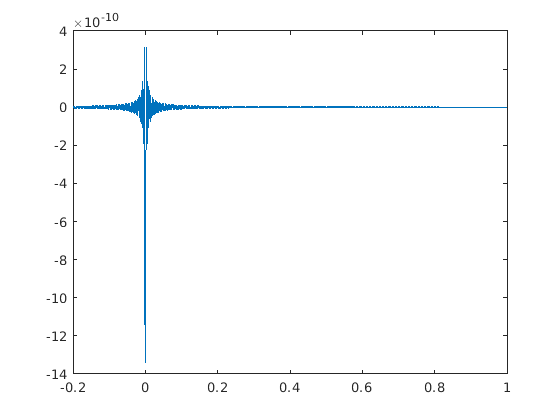

rt = g * s;
plot(t,rt)

function s = st(t,bandwidth)


    s = sin(pi*bandwidth*t) / (pi*bandwidth*t);
 

end



function [s, s_t, g,t] = greens(seconds,bandwidth,xs,zs,xr,zr,j,h, c)

    j = [1:j];
    dt = 1/(4*bandwidth);
    t = [-0.2:dt:seconds];
    g = zeros(length(j),length(t));
    s = zeros(size(t));
    s_t = s;
     
    for k = 1:length(j)
        
        if mod(j,2) == 0  
        
            r = sqrt((xr-xs)^2 + (zr-zs + j(k) * h)^2);
            e = 1;
        else   
            r = sqrt((xr-xs)^2 + (zr+zs - (j(k) +1) * h)^2);
            e = -1;
        end
     
        
        for i = 1:length(t)
            
            s(i) = st(t(i),bandwidth);
            ts = (t(i) - (r/c));
            s_t(i)= st(ts,bandwidth);
            
            g(j,i) = (e/(4*pi*r)) * s_t(i);
        
        end
        
    end 
    
    g = -sum(g,"all")
    
end
